% Define the plant's transfer function G(s)
num = 1.3 * [1 12];  % Numerator coefficients
den = conv(conv([1 3], [1 5]), [1 2]);  % Denominator coefficients
G = tf(num, den);  % Transfer function G(s)

% Set initial guess for PID parameters
initial_guess = [1, 1, 1]; % Initial guess for [Kp, Ki, Kd]

% Optimization options
options = optimset('Display', 'iter'); % Display iteration progress

% Modify the function call to include G
optimized_params = fminsearch(@(params) computeITAE(params, G), initial_guess, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1          3.83059         
     1            4          3.44655         initial simplex
     2            5          3.44655         reflect
     3            7          3.17979         expand
     4            9          2.88299         expand
     5           11          2.49614         expand
     6           13          2.20533         expand
     7           15            1.957         expand
     8           17          1.51076         expand
     9           18          1.51076         reflect
    10           19          1.51076         reflect
    11           21          1.51076         contract inside
    12           23          1.30203         expand
    13           24          1.30203         reflect
    14           26          1.01302         expand
    15           27          1.01302         reflect
    16           29         0.602208         expand
    17           30         0.602208      

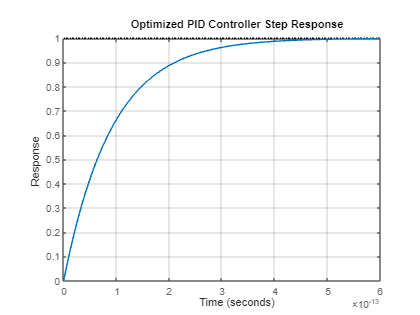


% Extract optimized PID parameters
Kp_opt = optimized_params(1);
Ki_opt = optimized_params(2);
Kd_opt = optimized_params(3);

% Implement the optimized PID controller
PID_optimized = pid(Kp_opt, Ki_opt, Kd_opt);

% Plot the optimized step response
figure;
step(feedback(PID_optimized * G, 1));
title('Optimized PID Controller Step Response');
xlabel('Time');
ylabel('Response');
grid on;


% Modify the computeITAE function to accept G as an input

function itae = computeITAE(params, G)
    Kp = params(1);
    Ki = params(2);
    Kd = params(3);
    
    % Create a PID controller
    PID = pid(Kp, Ki, Kd);
    
    % Closed-loop system with PID controller
    ClosedLoopSystem = feedback(PID * G, 1);
    
    % Simulate the step response
    [y, t] = step(ClosedLoopSystem, 0:0.01:10); % Adjust the time vector as needed
    setpoint = 1; % Assume a unit step input
    e = setpoint - y; % Error signal
    
    % Compute ITAE
    itae = trapz(t, t.*abs(e));
end

